## Association of clinically significant **AS** with physical exam variables

Here I want to explore the group characteristics of the cohort consisting of subjects with presence AS. One of the motivations for this investigation is to get a sense of how good cardiac auscultation is at predicting AS. First we define the dataset.

Ind = HSdata0.ASGRADE_T72>0;
dataSick    = HSdata0(Ind,:);
dataHealthy = HSdata0(~Ind,:);

What is the **gender** **distribution** of the disease?

mean(dataSick.SEX_T7==1)

ans = 0.6304

mean(dataHealthy.SEX_T7==1)

ans = 0.4561

We see that the **males** are far **overrepresented **and that gender is **significant**. What about **age**?

mean(dataSick.AGE_T7)

ans = 74.5652

mean(dataHealthy.AGE_T7)

ans = 63.7672

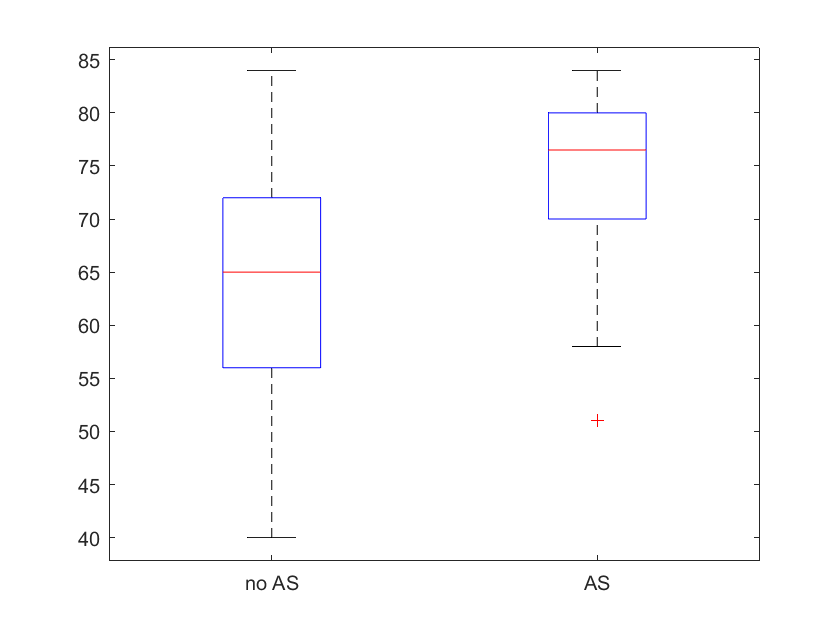

boxplot(HSdata0.AGE_T7,log2cat(Ind,"AS","no AS"));

As expected, AS is **associated** with **old** age, and age is **significant**. Dyspnoe, or laboured **breathing**, is an important risk factor.

mean(dataSick.DYSPNEA_FAST_UPHILL_T7==1,'omitnan')

ans = 0.5652

mean(dataHealthy.DYSPNEA_FAST_UPHILL_T7,'omitnan')

ans = 0.3860

We see that there is a significant difference, **56.5%** vs **38.6%**, a difference of about **17.9%**. Dyspnea is **significant**. Is the "fast uphill" better at separating the two cohorts?

mean(dataSick.DYSPNEA_CALMLY_FLAT_T7==1,'omitnan')

ans = 0.0870

mean(dataHealthy.DYSPNEA_CALMLY_FLAT_T7==1,'omitnan')

ans = 0.0250

mean(dataSick.DYSPNOE_WASHING_DRESSING_T7==1,'omitnan')

ans = 0.1087

mean(dataHealthy.DYSPNOE_WASHING_DRESSING_T7==1,'omitnan')

ans = 0.0298

mean(dataSick.DYSPNOE_REST_T7==1,'omitnan')

ans = 0

mean(dataHealthy.DYSPNOE_REST_T7==1,'omitnan')

ans = 0.0062

We are probably best of using the fast uphill test. Lets have a look at whether or not chest pain predicts AR.

mean(dataSick.CHEST_PAIN_FAST_T7==1,'omitnan')

ans = 0.1304

mean(dataHealthy.CHEST_PAIN_FAST_T7==1,'omitnan')

ans = 0.0874

it predicts it somewhat. Next let have a look at BMI. It is concievable that fat people are more likely to have AR.

mean(dataSick.BMI_T7,'omitnan')

ans = 26.7870

mean(dataHealthy.BMI_T7,'omitnan')

ans = 27.1908

BMI is actually somewhat lower for the AR cohort, but that is likely due to the fact that AR corellates strongly with age, and old people tend to be underweight. What about smoking status?

mean(dataSick.SMOKE_DAILY_Q2_T7==1,'omitnan')

ans = 0.1304

mean(dataHealthy.SMOKE_DAILY_Q2_T7==1,'omitnan')

ans = 0.1162

Higher prevalence of smoking amongst sick people, but not by much. What about blood pressure?

mean(dataSick.HIGH_BLOOD_PRESSURE_T7>=1,'omitnan')

ans = 0.5652

mean(dataHealthy.HIGH_BLOOD_PRESSURE_T7>=1,'omitnan')

ans = 0.3577

And here we have a **strong** predictor, high blood pressure. In the sick AS cohort **56.5%** had high bloodpressure, whereas the healthy cohort had a **35.8%** high bloodpressure. Next we look at Heart attack:

mean(dataSick.HEART_ATTACK_T7>=1,'omitnan')

ans = 0.1957

mean(dataHealthy.HEART_ATTACK_T7>=1,'omitnan')

ans = 0.0629

No surprises there, there is higher prevalence of heart attack in the AS group, **19.6%** vs **6.3%**. I thought it would be more.

mean(dataSick.HEART_FAILURE_T7>=1,'omitnan')

ans = 0.1087

mean(dataHealthy.HEART_FAILURE_T7>=1,'omitnan')

ans = 0.0317

**Same conclusion** as above.

mean(dataSick.COUGH_DAILY_T7>=1,'omitnan')

ans = 0.2391

mean(dataHealthy.COUGH_DAILY_T7>=1,'omitnan')

ans = 0.1651

Coughing is not a strong predictor of AR. 

Next lets have a look at PO2 max, which measures blood oxygen saturation, and how effective the lungs are at pulling O2 from the air.

mean(dataSick.PO2_T72,'omitnan')

ans = 97.5116

mean(dataHealthy.PO2_T72,'omitnan')  

ans = 97.6485

No difference. What about Lung capacity as measured by a spirometry?

mean(dataSick.PULSESPIRO_T72<60,'omitnan')

ans = 0.3913

mean(dataHealthy.PULSESPIRO_T72<60,'omitnan') 

ans = 0.3332

A somewhat significant group difference. The AS group had a **39.1%** prevalence of scoring less than 60 on the test, whereas for the healthy group the number was only **33.3%**. Finally, for good measure, we look at the predictive value of maximum murmur grade for predicting AR.

mean(dataSick.maxMeanMurGrade>=2,'omitnan')

ans = 0.8913

mean(dataHealthy.maxMeanMurGrade>=2,'omitnan') 

ans = 0.0888

risk of murmur grade >= 3 is **89.1%** for the sick group, and **8.9%** for the healthy group. **Murmur grade is higly predictive of AS**.

### conclusions:

Age, sex, dyspnea fast upphill, high bloodpressure, chest pain, pulse spiro, and murmur grade are significant predictors of significant AR. Let us throw them all into a regression model, but first we have to see how much data is available to model.

data = HSdata0;
Inan = isnan(data.SEX_T7)+isnan(data.AGE_T7)+isnan(data.DYSPNEA_FAST_UPHILL_T7)+...
    isnan(data.HIGH_BLOOD_PRESSURE_T7) + isnan(data.PULSESPIRO_T72) +...
    isnan(data.CHEST_PAIN_FAST_T7) + isnan(data.ASGRADE_T72);
Inan = (Inan>=1);
sum(Inan)

ans = 231

we loose 231 samples.  Will exclusion of the nan entries bias our findings?

mean(data.ASGRADE_T72(~Inan)>0)

ans = 0.0211

mean(data.ASGRADE_T72>0)

ans = 0.0216

sum(~Inan)

ans = 1898

 We have 0.1% increase in prevalence of significant AS, which we conclude to be **insiginificant source of bias**. Now we **model**.

dataMdl = data(~Inan,:);
ASsig = table(dataMdl.ASGRADE_T72>0,'VariableNames',{'ASsig'});
dataMdl = [dataMdl, ASsig];

dataMdl.SEX_T7 = categorical(dataMdl.SEX_T7);
dataMdl.DYSPNEA_FAST_UPHILL_T7 = categorical(dataMdl.DYSPNEA_FAST_UPHILL_T7);
dataMdl.HIGH_BLOOD_PRESSURE_T7 = categorical(dataMdl.HIGH_BLOOD_PRESSURE_T7>0);
dataMdl.CHEST_PAIN_FAST_T7     = categorical(dataMdl.CHEST_PAIN_FAST_T7);

formula = strcat('ASsig ~ AGE_T7 + SEX_T7 + HIGH_BLOOD_PRESSURE_T7 +',...
     'DYSPNEA_FAST_UPHILL_T7 + CHEST_PAIN_FAST_T7 + PULSESPIRO_T72')

formula = 'ASsig ~ AGE_T7 + SEX_T7 + HIGH_BLOOD_PRESSURE_T7 +DYSPNEA_FAST_UPHILL_T7 + CHEST_PAIN_FAST_T7 + PULSESPIRO_T72'

glm = fitglm(dataMdl,formula,'distr','binomial')

glm = Generalized linear regression model:
    logit(ASsig) ~ 1 + AGE_T7 + SEX_T7 + HIGH_BLOOD_PRESSURE_T7 + CHEST_PAIN_FAST_T7 + DYSPNEA_FAST_UPHILL_T7 + PULSESPIRO_T72
    Distribution = Binomial

Estimated Coefficients:
                                    Estimate        SE        tStat        pValue  
                                   __________    ________    ________    __________

    (Intercept)                       -12.595      2.0045     -6.2832     3.316e-10
    AGE_T7                            0.11729    0.022712      5.1641    2.4155e-07
    SEX_T7_1                          0.70087     0.34251      2.0463       0.04073
    HIGH_BLOOD_PRESSURE_T7_true       0.22839     0.33144     0.68911       0.49076
    CHEST_PAIN_FAST_T7_1             -0.39352     0

Get **performance curve** for prediction of significant AS:

glm.predict

ans =     0.0236
    0.0414
    0.0169
    0.0263
    0.0386
    0.0247
    0.0651
    0.0713
    0.0172
    0.0172


[X,Y,T,AUC] = perfcurve(dataMdl.ASsig, glm.predict, true)

X =          0
    0.0005
    0.0005
    0.0011
    0.0016
    0.0022
    0.0022
    0.0027
    0.0032
    0.0038


Y =          0
         0
    0.0250
    0.0250
    0.0250
    0.0250
    0.0500
    0.0500
    0.0500
    0.0500


T =     0.1766
    0.1766
    0.1714
    0.1593
    0.1546
    0.1498
    0.1480
    0.1469
    0.1464
    0.1442


AUC = 0.8005

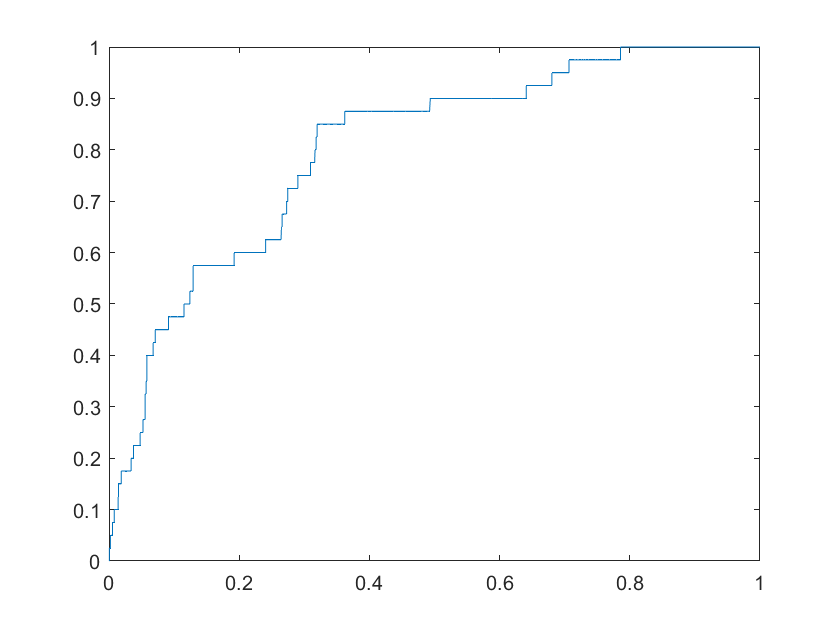

clf
plot(X,Y)

We get an AUC of **80.1% **for predicting** clinically significant AR**. This is surprisingly good! What happens if we model using **only** murmur grade?

[~,~,~,AUC1] = perfcurve(dataMdl.ASsig, dataMdl.Murmur_1_grade_ref_ny_T72, true)

AUC1 = 0.9127

[~,~,~,AUC2] = perfcurve(dataMdl.ASsig, dataMdl.Murmur_2_grade_ref_ny_T72, true)

AUC2 = 0.9126

[~,~,~,AUC3] = perfcurve(dataMdl.ASsig, dataMdl.Murmur_3_grade_ref_ny_T72, true)

AUC3 = 0.9247

[~,~,~,AUC4] = perfcurve(dataMdl.ASsig, dataMdl.Murmur_4_grade_ref_ny_T72, true)

AUC4 = 0.9290

[X,Y,~,AUC]  = perfcurve(dataMdl.ASsig, dataMdl.maxMeanMurGrade, true)

X =          0
    0.0011
    0.0022
    0.0054
    0.0140
    0.0334
    0.0544
    0.0877
    0.1249
    0.1658


Y =          0
    0.0750
    0.2250
    0.4250
    0.5750
    0.7000
    0.7750
    0.8750
    0.9000
    0.9250


AUC = 0.9523

[AUC1,AUC2,AUC3,AUC4,AUC]'

ans =     0.9127
    0.9126
    0.9247
    0.9290
    0.9523


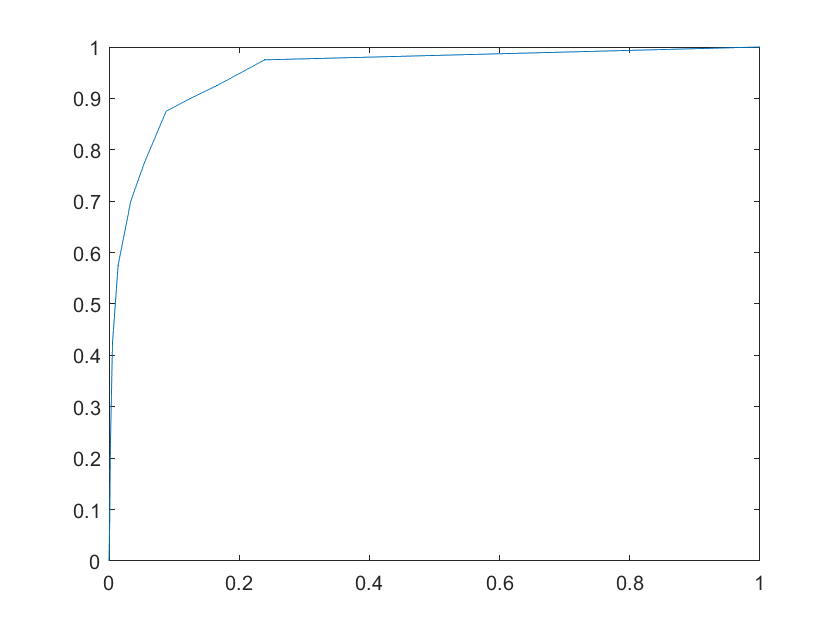

clf
plot(X,Y)

When we use only max murmur grade to predict AR, we get an AUC of **91.2%**. This is better than I thought it would be. Cleary, using the other covariates results in a much better model. Finally, lets try adding murmur grade to the **full model.**

formula = strcat('ASsig ~ AGE_T7 + SEX_T7 + HIGH_BLOOD_PRESSURE_T7 +',...
     'DYSPNEA_FAST_UPHILL_T7 + CHEST_PAIN_FAST_T7 + PULSESPIRO_T72 + maxMeanMurGrade')

formula = 'ASsig ~ AGE_T7 + SEX_T7 + HIGH_BLOOD_PRESSURE_T7 +DYSPNEA_FAST_UPHILL_T7 + CHEST_PAIN_FAST_T7 + PULSESPIRO_T72 + maxMeanMurGrade'

glm = fitglm(dataMdl,formula,'distr','binomial')

glm = Generalized linear regression model:
    logit(ASsig) ~ 1 + AGE_T7 + SEX_T7 + HIGH_BLOOD_PRESSURE_T7 + CHEST_PAIN_FAST_T7 + DYSPNEA_FAST_UPHILL_T7 + PULSESPIRO_T72 + maxMeanMurGrade
    Distribution = Binomial

Estimated Coefficients:
                                   Estimate       SE        tStat        pValue  
                                   ________    ________    ________    __________

    (Intercept)                     -12.722      2.3925     -5.3175    1.0519e-07
    AGE_T7                         0.057028    0.025703      2.2187      0.026504
    SEX_T7_1                         1.3988     0.43916      3.1851     0.0014469
    HIGH_BLOOD_PRESSURE_T7_true    -0.12754     0.41376    -0.30825       0.75789
    CHEST_PAIN_FAST_T7_1           0.030339  


[X,Y,T,AUC] = perfcurve(dataMdl.ASsig, glm.predict, true)

X =          0
         0
    0.0005
    0.0011
    0.0011
    0.0011
    0.0011
    0.0011
    0.0011
    0.0011


Y =          0
    0.0250
    0.0250
    0.0250
    0.0500
    0.0750
    0.1000
    0.1250
    0.1500
    0.1750


T =     0.9204
    0.9204
    0.8569
    0.8307
    0.8198
    0.8176
    0.8134
    0.8049
    0.7880
    0.7820


AUC = 0.9693

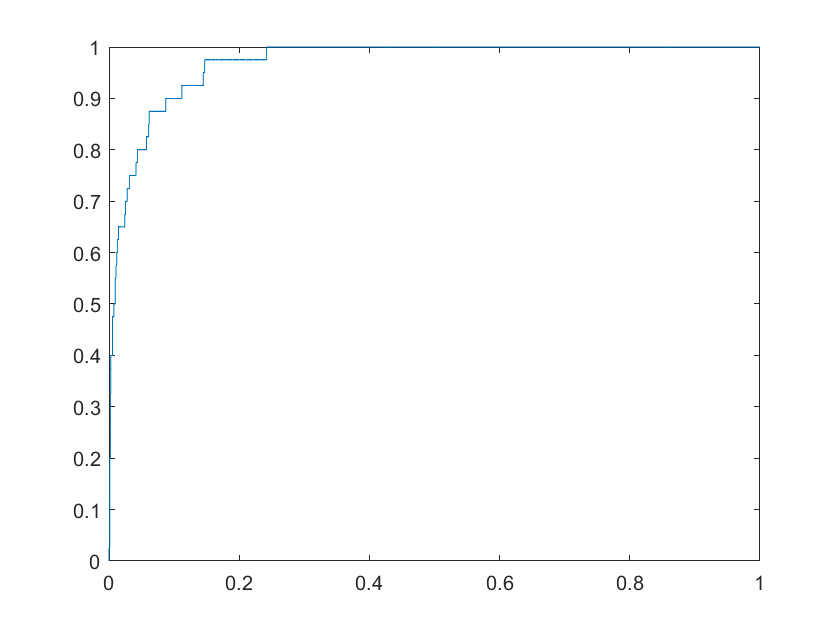

clf
plot(X,Y)

We get an AUC of **96.9%**, which is an increase of **5.7%**. This is significant. Dyspnea, chest pain, 

formula = strcat('ASsig ~ AGE_T7 + SEX_T7  +',...
     ' maxMeanMurGrade')

formula = 'ASsig ~ AGE_T7 + SEX_T7  + maxMeanMurGrade'

glm = fitglm(dataMdl,formula,'distr','binomial')

glm = Generalized linear regression model:
    logit(ASsig) ~ 1 + AGE_T7 + SEX_T7 + maxMeanMurGrade
    Distribution = Binomial

Estimated Coefficients:
                       Estimate       SE        tStat       pValue  
                       ________    ________    _______    __________

    (Intercept)          -10.98      1.9161    -5.7304    1.0017e-08
    AGE_T7             0.058426    0.025601     2.2822      0.022478
    SEX_T7_1             1.2659      0.4155     3.0467     0.0023139
    maxMeanMurGrade      1.4846     0.15554     9.5444    1.3695e-21


1898 observations, 1894 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant model: 195, p-value = 4.87e-42


[X,Y,T,AUC] = perfcurve(dataMdl.ASsig, glm.predict, true)

X =          0
         0
         0
    0.0005
    0.0005
    0.0005
    0.0005
    0.0005
    0.0011
    0.0016


Y =          0
    0.0250
    0.0500
    0.0500
    0.0750
    0.1000
    0.1250
    0.1500
    0.2000
    0.2000


T =     0.8716
    0.8716
    0.8454
    0.8431
    0.8376
    0.7942
    0.7562
    0.7194
    0.7106
    0.7070


AUC = 0.9668

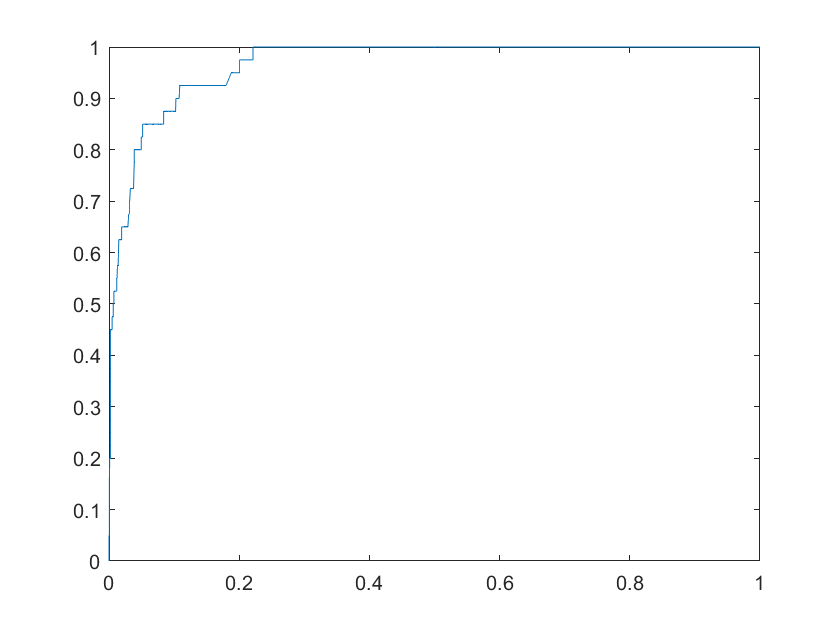

clf
plot(X,Y)

The AUC is now **96.7%. **The AUC when using recordings from only one area was** 94.6%, 94.42%, 94.9% **and** 95.6%, **so using maximum murmur grade was benificial. This is very exciting. Using only age, sex and maximum murmur grade we are able to predict AS presence with an AUC close to 100. In a paper published in 1988, sensitivity and specificity for detecting moderate to severe AS was only **83%** and **79%** respectively, which corresponds to an AUC of **81%**.

### conclusion:

Murmur grade is accurate for detecting even mild cases of AS. Using Sex and Age in a multivariate model achieves even greater accuracy. The implication of these results is that AS can be predicted with high accuracy at home using an app if we were to implement the murmur detection algorithm. This can allow assymptomatic patients to be detected much earlier, and can save doctors time.